**PROYECTO - CLASIFICACIÓN DE ECG Y EXTRACCIÓN DE CARACTERÍSTICAS SIMPLES**

**Integrantes:**

**Nombre:** Anyi Valentina Benites Gutiérrez   **Código:** 20181168204

**Nombre:** Edward Reina Hortua ** Código:** 20172164250

**Nombre:** Nicolás A. Losada Sanchez  **Código:** 20182174071

**Cargar y Preprocesar Datos**

Primero se carga el archivo PhysionetData.mat y se visualizan las primeras 5 filas de las variables Signals y Labels:

load PhysionetData.mat

cinco_signals = Signals(1:5,1)

cinco_signals = 5×1 cell array
    {1×9000  double}
    {1×9000  double}
    {1×18000 double}
    {1×9000  double}
    {1×18000 double}


cinco_labels = Labels(1:5,1)

cinco_labels = 5×1 categorical array
     N 
     N 
     N 
     A 
     A 


Se obtiene la siguiente salida:

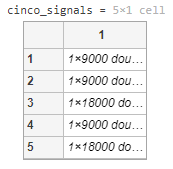

Ahora mediante el comando "summary" se observa la cantidad de señales con Ritmo Sinusal Normal (N) y con Arritmia (A):

summary(Labels)

     A       738 
     N      5050 


Observamos que hay un mayor numero de señales con ritmo Sinusal Normal (5050).

Se crea un histograma con el fin de visualizar la longitud de las señales, para lo cual se utiliza la función "plotSignalLengths":

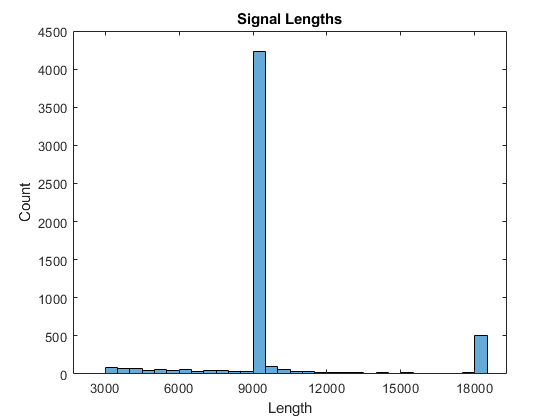

plotSignalLengths(Signals)

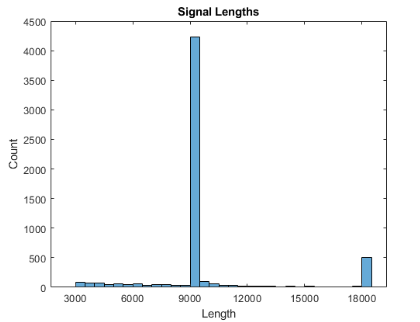

Se puede visualizar que la mayoria de señales tienen una longitud de 9000 muestras, le sihuen las tienen una longitud de 18000 muestras y hay algunas dentro del rango de 3000 a 18000.

Se procede a observar un segmento de una señal de cada clase (N y A):

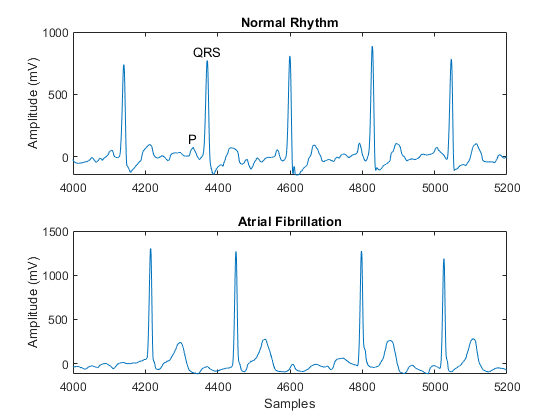

figure(2)
visualizeECGSignals(Signals)

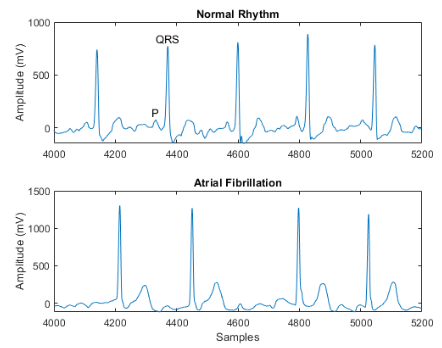

En la grfica superior se observa una señal con Ritmo Sinusal Normal y en la grafica inferior una señal con arritmia, se puede identificar que la señal con arritmia es muy irregular con respecto a la señal con ritmo normal, la amplirud de la señal con arritmia es mayor y carece de la onda P, además el numero de latidos es de cuatro y en la señal de ritmo normal son cinco, esto en el mismo intervalo de muestras.

A continuación se utiliza la función "segmentSignals" con el fin de redimensionar las señales a 9000 muestras y se realiza un histograma con el fin de verificar la longitud redimensionada.

redimension = segmentSignals(Signals,Labels)

redimension = 5655×1 cell array
    {1×9000 double}
    {1×9000 double}
    {1×9000 double}
    {1×9000 double}
    {1×9000 double}
    {1×9000 double}
    {1×9000 double}
    {1×9000 double}
    {1×9000 double}
    {1×9000 double}
    {1×9000 double}
    {1×9000 double}
    {1×9000 double}
    {1×9000 double}
    {1×9000 double}
    {1×9000 double}


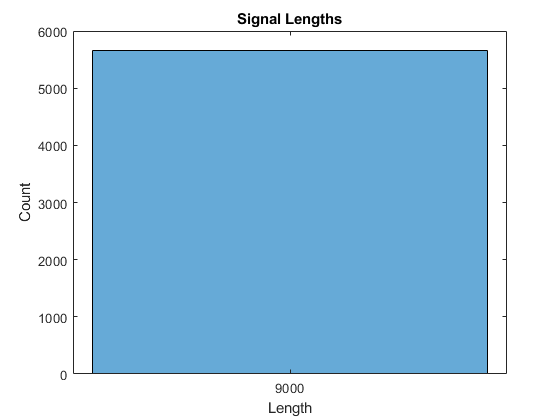

figure(3)
plotSignalLengths(redimension) 

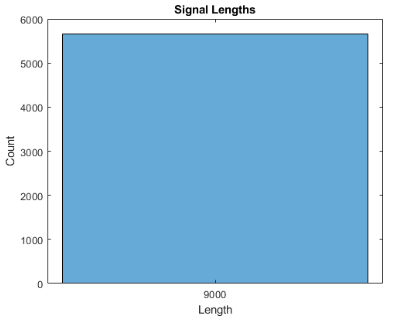

**Extraer Características**

Se separan las señales con Ritmo Sinusal Normal (N) de las señales con Arritmia (A) y se guardan en variables separadas, luego con la función "plotBothHistograms" se crea un histograma con el fin de visualizar las medidas estadisticas de cada grupo de señales:

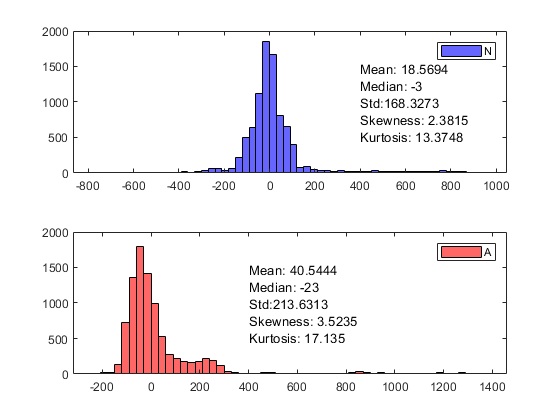

normal_N = {};
arritmia_A = {};
N = 1;
A = 1;
for i=1:5788
    if Labels(i,1) == "N"
        normal_N(N,1) = Signals(i,1);
        N = N+1;
    else
        arritmia_A(A,1) = Signals(i,1);
        A = A+1;
    end
end
figure(4)
plotBothHistograms(normal_N,arritmia_A,Labels)

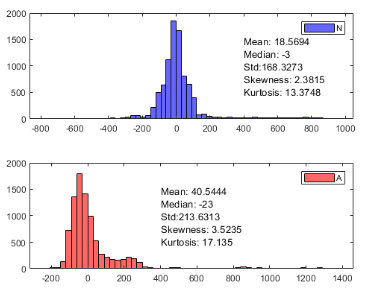

Se puede observar que las caracteristicas varian de acuerdo a cada tipo de señal, ademas de dichas caracteristicas se agregan la desviación media absoluta, cuantiles 25 y 75, y el rango intercuartílico de la señal, para lo cual se utilizará la función "extractFeatures", la cual genera una tabla que contiene las 10 medidas estadisticas de las señales:

figure(5)
featuresTable = extractFeatures(Signals,Labels)

featuresTable = 5788×10 table
    meanValue    medianValue    standardDeviation    meanAbsoluteDeviation    quantile25    quantile75    signalIQR    sampleSkewness    sampleKurtosis    class
    _________    ___________    _________________    _____________________    __________    __________    _________    ______________    ______________    _____

      18.569          -3             168.33                 91.847                -44           42            86            2.3815           13.375          N  
      21.241          -9             176.66                 101.92                -54           54           108            3.1578           20.77

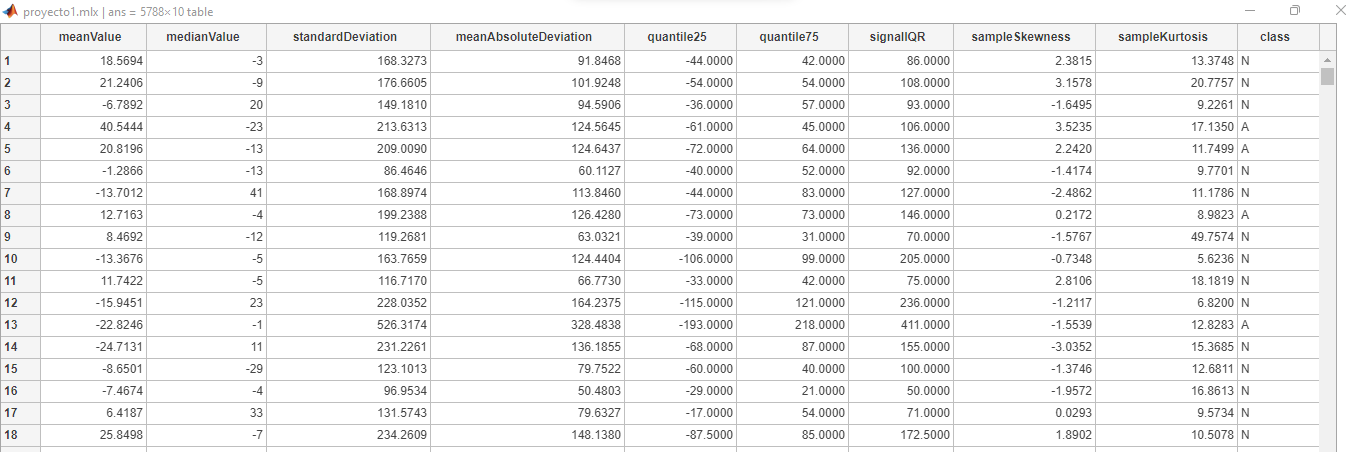

De este modo se crea la tabla que contiene las 10 medidas estadisticas para todas las señales.

**Preparar datos para el entrenamiento**

Mediante el comando "cvpartition"  dividimos el 80% de los datos para el entrenamiento y el el resto se utiliza para las pruebas, dichas señales se guardan en las variables TrainData y TestData respectivamente, luego se visualiza la cantidad de señales con Ritmo Sinusal Normal (N) y con Arritmia (A) de TrainData y TestData.

n = length(featuresTable.class);
partition = cvpartition(n,"Holdout",0.2);

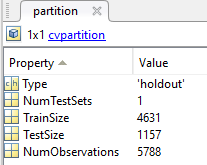

Se puede observar que el 80% de los datos se asignaron a TrainSize y el 20% restante a TestSize, luego se le asigna a las variables TrainData y TestData su porcentaje de señales correspondiente:

idxTrain = training(partition);
TrainData = featuresTable(idxTrain,:);
fprintf("Señales TrainData")

Señales TrainData

summary(TrainData.class)

     A       578 
     N      4053 



idxTest = test(partition);
TestData = featuresTable(idxTest,:);
fprintf("Señales TestData")

Señales TestData

summary(TestData.class) 

     A      160 
     N      997 


De éste modo se observa la cantidad de señales correspondiente a cada grupo de datos.

**Entrenar usando Classification Learner**

Ahora, mediante la herramienta "classificationLearner", se utiliza la varible TrainData con el fin de entrenar un modelo, ésta herramienta nos permite probar muchas técnicas de modelado diferentes de manera muy rapida, los resultados fueron los siguientes:

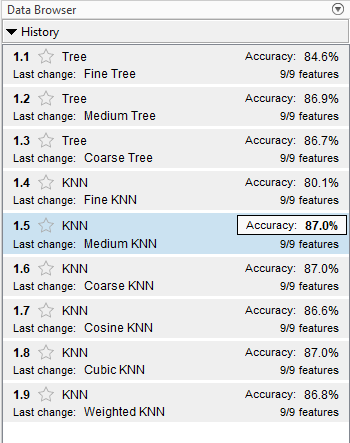

Se puede observar que el modelo de mayor precisión fue de 87.0% y su matriz de confusión fue:

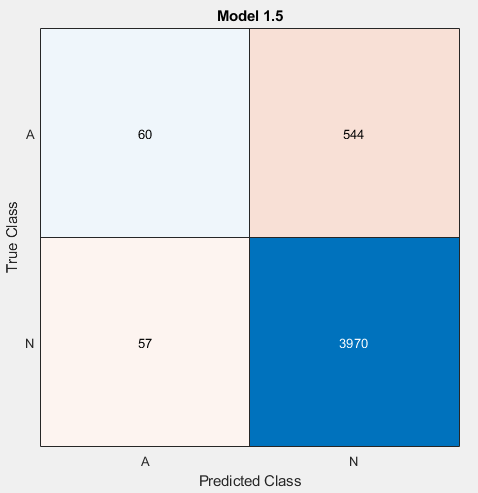

En la matriz de confusión se observa que hay una cantidad elevada de falsos negativos para la señal con arritmia A (544), ésto se debe principalmente a que el modelo está sesgado hacia la señal normal N, ya que son el mayor numero de señales (5050) en comparación con las señales con arritmia A (738), por lo tanto se genera un desequilibrio.

**Abordar el Desequilibrio de Datos**

Con el fin de reducir el desequilibrio, se edita la matriz de "costos de clasificación erronea", fijando el falso negativo como 4 veces mas importante que el falso positivo, obteniendo la siguiente salida:

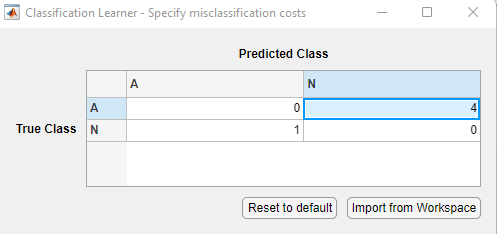

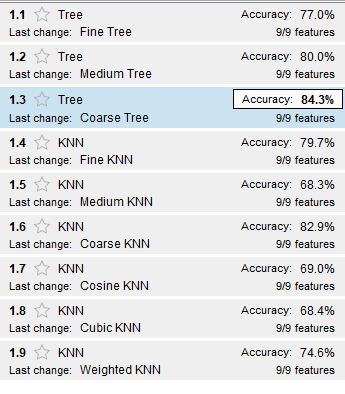

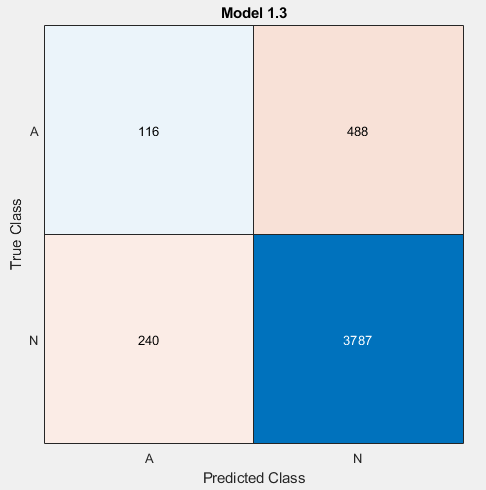

Se puede observar que el numero de falsos negativos disminuyó de 544 a 488, tambien aumentó el numero de verdaderos positivos de 60 a 116, sin embargo se redujo el porcentaje de precisión y se aumentó el numero de falsos positivos, sin embargo, se considera que el numero de falsos postitivos no es tan importante como el numero de falsos negativos, ya que fue la relación que se fijó en la matriz de costos de clasificación erronea.

**Evaluar el Modelo Entrenado**

A continuación se evalúa el modelo entrenado con los datos de la variable TestData, para lo cual se exporta el modelo como una función llamada "trainClassifier" los resultados obtenidos son los siguientes:

[trainedClassifier, validationAccuracy] = trainClassifier(TestData)

trainedClassifier = struct with fields:
            predictFcn: @(x)treePredictFcn(predictorExtractionFcn(x))
     RequiredVariables: {'meanAbsoluteDeviation'  'meanValue'  'medianValue'  'quantile25'  'quantile75'  'sampleKurtosis'  'sampleSkewness'  'signalIQR'  'standardDeviation'}
    ClassificationTree: [1×1 ClassificationTree]
                 About: 'This struct is a trained model exported from Classification Learner R2020a.'
          HowToPredict: 'To make predictions on a new table, T, use: ↵  yfit = c.predictFcn(T) ↵replacing 'c' with the name of the variable that is this struct, e.g. 'trainedModel'. ↵ ↵The table, T, must contain the variables returned by: ↵  c.RequiredVariables ↵Variable formats (e.g. matrix/vector, datatype) must match the original training data. ↵Additional variables are ignored. ↵ ↵For more information, see How to predict using an exported model

validationAccuracy = 0.8807

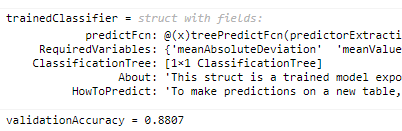

Se observa que el modelo clasifica las señales con una precisión del 88.07%.

Debido a el desequilibro en los datos y que no se tienen caracteristicas bien definidas, en general los modelos son muy imprecisos, por lo tanto si se quiere mejorar los modelos, lo principal es mejorar lo mencionado anteriormente.